# Linearized Kalman Filter

% Bringing in required functions and variables 
% bringing in simulation data and provided data
load sim_setup.mat
load orbitdetermination-finalproj_data_2023_11_14.mat
addpath('./functions/')

## Useful Constants

m = length(a_SRP);  % number of inputs equals the length of this vector
p = 2;              % number of measurement variables per landmark

% chosen step size
dt = dt_int;
% dt = dt_obs;

% non-linear simualtion
x_pert = [1e-5,1e-5,1e-5,1e-7,1e-7,1e-7]';

## LKF

% --- Non-linear simulation ---
x_0 = [r_nom; dr_nom];
options = odeset('RelTol',1e-12);
t_obs = unique(y_table(:, 1));          % times of observations [s]
t_ode45 = 0:dt:max(t_obs);
[t,x_ode45] = ode45(@(t_in,x_in) orbit(t_in,x_in,a_SRP,mu_A), t_ode45, x_0, options);
[steps,n] = size(x_ode45);

% --- Static system matrices ---
% CT B matrix
B = zeros(n,m);
B(4:end,:) = eye(3);

% Static input
u = a_SRP;

% CT Gamma matrix 
Gamma = zeros(n,m);
Gamma(4:end,:) = eye(3);

% CT Noise matrices
W = eye(m)*sig_w^2;
V = eye(p)*sig_v^2;
R = V/dt;

% --- number of landmarks to use --- 
num_marks = length(pos_lmks_A);
lps = pos_lmks_A(:,1:num_marks);

% --- Initializing vectors for LKF --- 
% creating useful vectors for all times 
dx_plus = zeros(steps,n);                               % state correction after measurment
X_plus = zeros(steps,n);                                % total state after measurement
P_plus = zeros(n,n,steps);                              % residuals after measurement
eps_X = zeros(steps,1);                                 % NEES
eps_y = zeros(steps,1);                                 % NIS

% initializing these vectors 
dx_plus(1,:) = x_pert';
X_plus(1,:) =  x_ode45(1,:) + x_pert';
P_plus(:,:,1) = diag([ones(1,3),ones(1,3)*1e-1])*1e-2;
eps_X(1) = dx_plus(1,:) * inv(P_plus(:,:,1)) * dx_plus(1,:)';
% could initialize eps_Y, but I'm not going to for now.

% --- Performing LKF ---
% in this for loop, the current time step is k-1
% and the next time step is time k
for k = 2:steps
    % --- processes for CURRENT time k-1 ---
    t_k = t(k-1);                                       % time for this time step
    x_nom_k = x_ode45(k-1,:)';                          % calculating nominal state for current time step k-1
    A = dfdx(x_nom_k,mu_A);                             % Jacobians for nominal state
    [F,G,Q] = state_CT_to_DT(dt,A,B,Gamma,W);           % Putting this in the discrete time 

    % Kalman filter prediction step
    dx_minus = F*dx_plus(k-1,:)' + G*u;
    P_minus = F*P_plus(:,:,k-1)*F' + Q;
    
    t_k_plus = t(k);
    if mod(t_k_plus,dt_obs) ~= 0                        % If no measurment is available at next time step, make no measurment updates
        x_nom_k_plus = x_ode45(k,:)';                   % calculating nominal state for next current time step k
        dx_plus(k,:) = dx_minus';                       % Next state pertibation is uncorrected predicted pertibation
        P_plus(:,:,k) = P_minus;                        % residuals for next state is the uncorrected residuals
        X_plus(k,:) = x_nom_k_plus' +  dx_minus';       % Next total state is the nominal plus the uncorrected at that state
        continue                                        % Do not make corrections; skip rest of loop
    end

    % --- processes for NEXT time step k, after measurement taken --- 
    % time, nominal state, and RNC matrix for next time step
    meas_idx = t_k_plus / dt_obs;
    x_nom_k_plus = x_ode45(k,:)';
    RNC = R_CtoN(:, :, meas_idx);                       % ADCS instrument axes at this step
    
    % initalizations of H and dy matrices
    H = ones(p*num_marks,n)*NaN;                        % all NaNs; visible landmarks will replace to non-NaNs 
    dy_all = ones(p*num_marks,1)*NaN;                   

    % perfoming H matrix calculations and simulated measurements for next time step
    for i = 1:num_marks
        lp = lps(:,i); % landmark i

        % getting expected position of landmark at next time step, with no
        % process nosie
        y_nom = y_measured(lp, x_nom_k_plus, RNC, t_k_plus,false,true); 
                
        % taking a simulated measurement with noise, at next time step
        y_meas = y_measured(lp, x_nom_k_plus, RNC, t_k_plus,true,true);

        % if not visible, skip this landmark
        if anynan(y_nom) || anynan(y_meas)
            continue
        end

        dy_i = y_meas - y_nom;                          % difference in measured vs. expected 

        % obtaining H matrix for this landmark at next time step
        H_i = H_k(lp,x_nom_k_plus,t_k_plus,RNC);
        
        % storing these values 
        rows = (p*(i-1)+1):(p*i);                       % Rows corresponding to this landmark
        dy_all(rows) = dy_i;                            % observation difference matrix
        H(rows,:) = H_i;                                % H matrix
    end
    
    % Creating dynamic H matrix 
    vis_rows = find(~isnan(H(:,1)));                    % finding all the non-NaN rows, corresponding to visible landmarks
    num_vis = length(vis_rows)/p;                       % number of visible landmarks (Each landmark has p measurements)
    R_k = kron(eye(num_vis),R);                         % measurement noise matrix. All landmarks have same noise, so diagonal matrix
    H = H(vis_rows,:);                                  % Getting rid of non-visible landmarks
    dy_vis = dy_all(vis_rows,:);
    
    % Kalman filter correction step
    S_k = H * P_minus * H' + R_k;                       % Innovation matrix
    K = P_minus * H' * inv(S_k);                        % Gain matrix
    e_y_k = dy_vis - H*dx_minus;                        % Measurement error
    dx_plus(k,:) = (dx_minus + K*(e_y_k))';             % correction for next time step
    P_plus(:,:,k) = (eye(n) - K*H)*P_minus;             % Uncertainties for next time step
    X_plus(k,:) = x_nom_k_plus' + dx_plus(k,:);         % Total estimate state for next step  

    % --- Error calculations ---
    % state error and NEES
    e_X_k = dx_plus(k,:)';
    eps_X(k) = e_X_k' * inv(P_plus(:,:,k)) * e_X_k;
    
    % measurement error and NIS 
    eps_y(k) = e_y_k' * inv(S_k) * e_y_k;
end

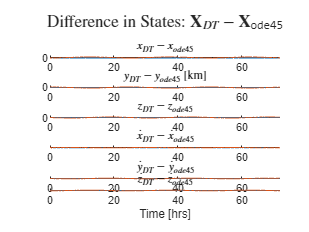

figure;
fig = tiledlayout(n,1);
titles =   ["$x_{DT} - x_{ode45}$", "$y_{DT} - y_{ode45}$ [km]","$z_{DT} - z_{ode45}$", ...
            "$\dot x_{DT} - \dot x_{ode45}$", "$\dot y_{DT} - \dot y_{ode45}$","$\dot z_{DT} - \dot z_{ode45}$"];
ylabels =   ["$\Delta x$ [km]", "$\Delta y$ [km]","$\Delta z$ [km/s]", ...
            "$\Delta \dot x$ [km/s]", "$\Delta \dot y$ [km/s]","$\Delta \dot z$ [km/s]"];
for i = 1:n
    nexttile(fig)
    hold on
    plot(t/60/60,X_plus(:,i)-x_ode45(:,i))
    plot(t/60/60,dx_plus(:,i)-x_ode45(:,i))
    hold off
    xlim([t_obs(1)/60/60, 72])
    title(titles(i),Interpreter='latex')
    ylabel(ylabels(i),Interpreter='latex')
end
xlabel("Time [hrs]")
title(fig,"Difference in States: $\textbf{X}_{DT} - \textbf{X}_{\texttt{ode45}} $", Interpreter='latex')